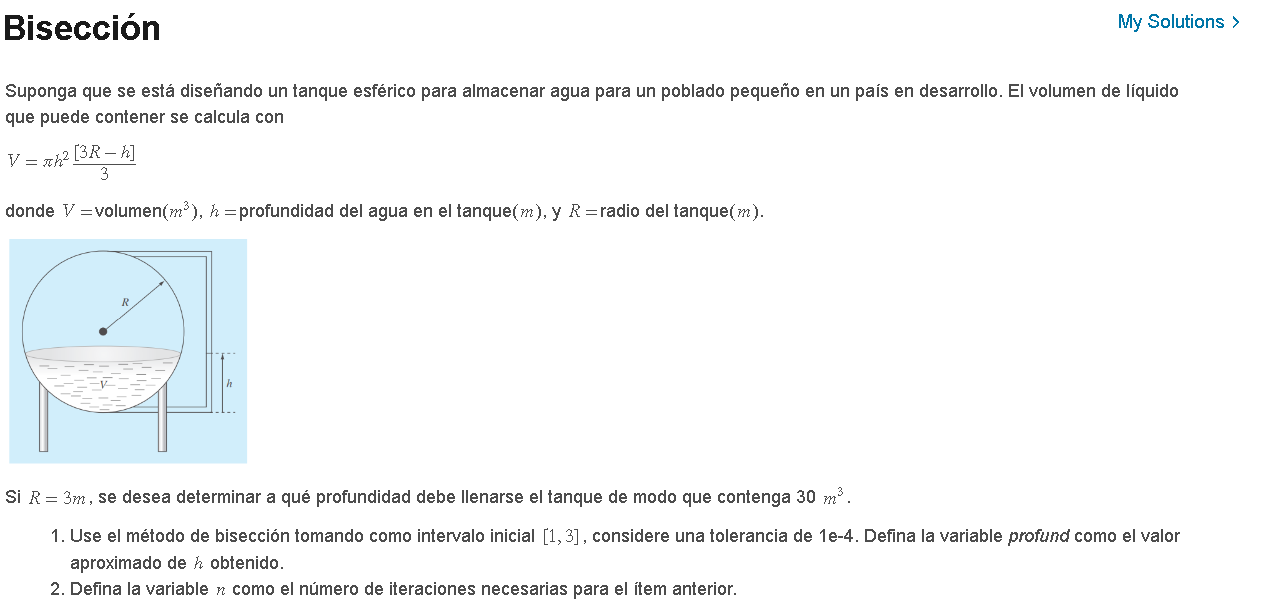

format long
syms h
R =3;
Vf=30;

V = matlabFunction((pi*h*h*(3*R-h)/3))

V = function_handle with value:
    @(h)h.^2.*pi.*(h-9.0).*(-1.0./3.0)



f = matlabFunction(V(h)-30)

f = function_handle with value:
    @(h)h.^2.*pi.*(h-9.0).*(-1.0./3.0)-3.0e+1




a=1;
b=3;
tole= 10^(-4);

historial = biseccion2(f, a,b,tole)

Se necesita 14 iteraciones


historial =    1.000000000000000   3.000000000000000   2.000000000000000 -21.622419590427221  26.548667764616269  -0.678468566495265   1.000000000000000
   2.000000000000000   3.000000000000000   2.500000000000000  -0.678468566495265  26.548667764616269  12.542400517361784   0.500000000000000
   2.000000000000000   2.500000000000000   2.250000000000000  -0.678468566495265  12.542400517361784   5.784703819796235   0.250000000000000
   2.000000000000000   2.250000000000000   2.125000000000000  -0.678468566495265   5.784703819796235   2.510166164589684   0.125000000000000
   2.000000000000000   2.125000000000000   2.062500000000000  -0.678468566495265   2.510166164589684   0.904343943138066   0.062500000000000
   2.000000000000000   2.062500000000000   2.031250000000000  -0.678468566495265   0.904343943138066   0.109965600544875   0.031250000000000
   2.000000000000000   2.031250000000000   2.015625000000000  -0.678468566495265   0.109965600544875  -0.285006489144234   0.015625000000000
 


[f1,c1]= size(historial);
title = ["a" "b" "c" "f(a)" "f(b)" "f(c)" "error"];
tabla=array2table(historial,"VariableNames",title);

profund=historial(end,3)

profund =    2.026916503906250


n=f1-1

n =     14


%grafiquita

%xx = [1:0.01:3];
%yy = V(xx);

%plot(xx,yy)



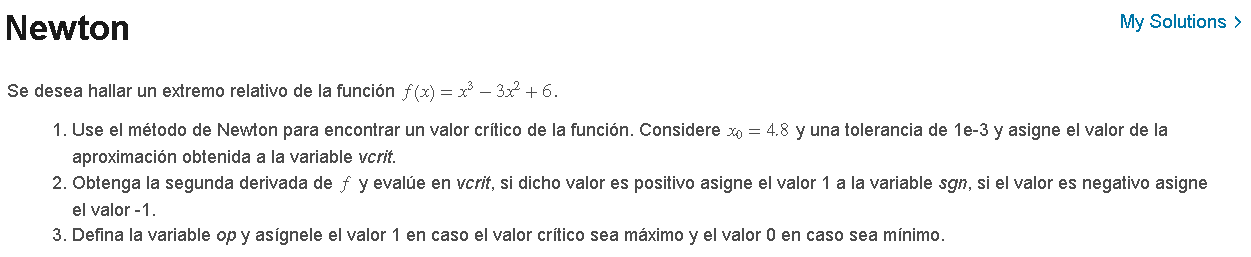


syms x

f= matlabFunction(x^(3)-3*x^(2)+6);
%para una variable
Df = matlabFunction(diff(f(x),1))

Df = function_handle with value:
    @(x)x.*-6.0+x.^2.*3.0


%DDf = matlabFunction(diff(f(x),2))
%DDDf = matlabFunction(diff(f(x),3))
%f(x)
%Df(x)
%DDf(x)

x0=4.8;
tole = 10^(-3);

%ITEM 1
rpt = newton(Df, x0, tole);

row =      6


col =      1


Se necesita 5 iteraciones


vcrit = rpt(end)

vcrit =    2.000000064620069




%ITEM 2
DDf = matlabFunction( diff(Df(x),x));
sgn=0;
if DDf(vcrit)>0
    sgn=1
elseif DDf(vcrit)<0
    sgn=-1
end 

sgn =      1



%ITEM 3
op=0;

if( sgn==-1)
    op = 1
else 
    op=0
end

op =      0



xx = [0: 0.01:5]

xx =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.4900000000

yy = f(xx)

yy =    6.000000000000000   5.999701000000000   5.998808000000000   5.997327000000000   5.995264000000000   5.992625000000000   5.989416000000000   5.985643000000000   5.981312000000000   5.976429000000000   5.971000000000000   5.965031000000000   5.958528000000000   5.951497000000000   5.943944000000000   5.935875000000000   5.927296000000000   5.918213000000000   5.908632000000000   5.898559000000000   5.888000000000000   5.876961000000000   5.865448000000000   5.853467000000000   5.841024000000000   5.828125000000000   5.814776000000000   5.800983000000000   5.786752000000000   5.772089000000000   5.757000000000000   5.741491000000000   5.725568000000000   5.709237000000000   5.692504000000000   5.675375000000000   5.657856000000000   5.639953000000000   5.621672000000000   5.603019000000000   5.584000000000000   5.564621000000000   5.544888000000000   5.524807000000000   5.504384000000000   5.483625000000000   5.462536000000000   5.441123000000000   5.419392000000000   5.3973490000

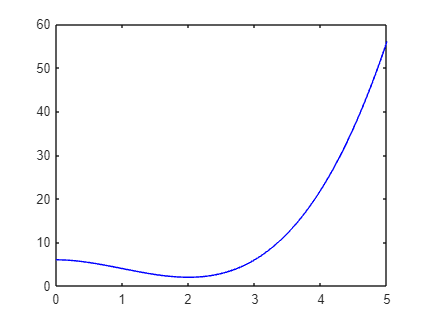


plot(xx,yy,"b")

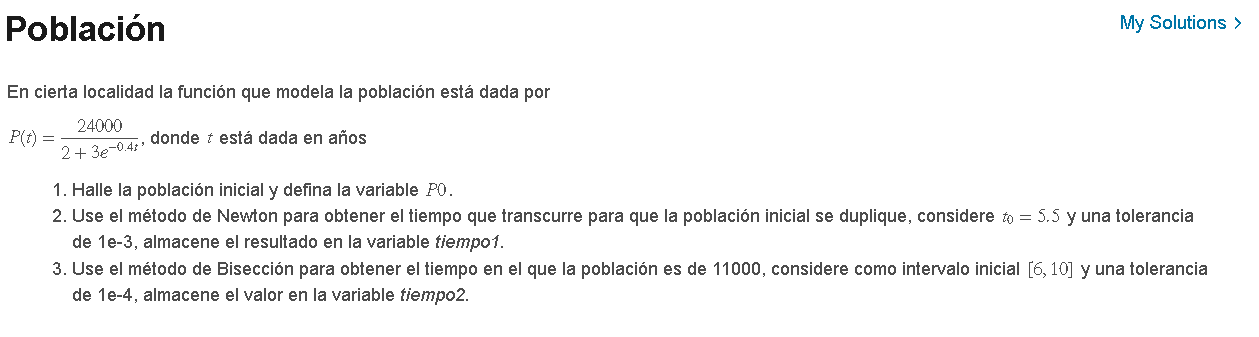

syms t

P = matlabFunction( 24000/(2+3*exp(-0.4*t)) )

P = function_handle with value:
    @(t)2.4e+4./(exp(t.*(-2.0./5.0)).*3.0+2.0)



%ITEM 1
P0 = P(0)

P0 =         4800



%ITEM 2
Pf=2*P0

Pf =         9600


t0 = 5.5

t0 =    5.500000000000000


tol = 10^(-3)

tol =      1.000000000000000e-03



%P(t) = 2*P0
% P(t)-2*P0=0

f = matlabFunction(P(t)-Pf)

f = function_handle with value:
    @(t)2.4e+4./(exp(t.*(-2.0./5.0)).*3.0+2.0)-9.6e+3


historial = newton(f, t0, tol);

row =      4


col =      1


Se necesita 3 iteraciones


[row1,col1] = size(historial);

tiempo1 = historial(row1)

tiempo1 =    4.479397735433510



%ITEM 3
Pf = 11000

Pf =        11000


a=6

a =      6


b=10

b =     10


tol2 = 10^(-4)

tol2 =      1.000000000000000e-04



f2 = matlabFunction(P(t)-Pf);

historial2 = biseccion2(f2, a,b,tol2);

Se necesita 15 iteraciones


[row2,col2]=size(historial2);
tiempo2 = historial2(row2,3)

tiempo2 =    7.008361816406250


%xx = [0:0.01:8]
%yy = P(xx)

%plot(xx,yy,"r")




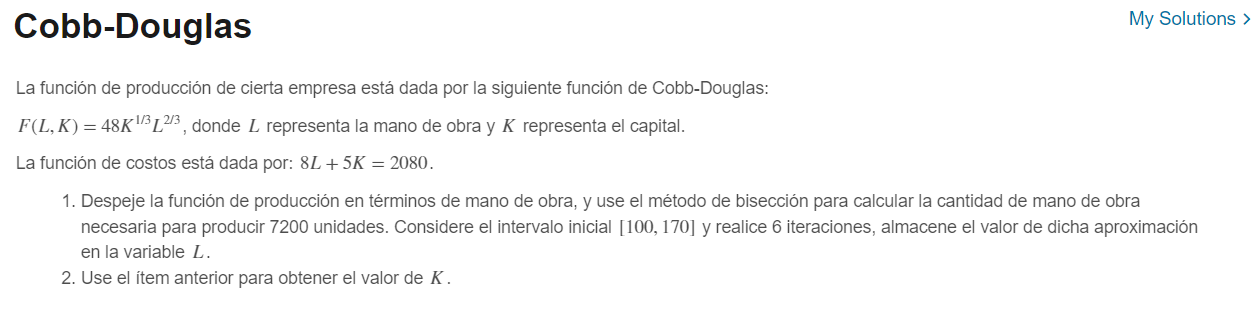

syms l

k = matlabFunction( (2080-8*l)/5 )

k = function_handle with value:
    @(l)l.*(-8.0./5.0)+4.16e+2



F = matlabFunction(48*( k(l)^(1/3) )*(l^(2/3)) )

F = function_handle with value:
    @(l)l.^(2.0./3.0).*(l.*(-8.0./5.0)+4.16e+2).^(1.0./3.0).*4.8e+1



a = 100;
b=170;

Ff = 7200;

f= matlabFunction(F(l)-Ff)

f = function_handle with value:
    @(l)l.^(2.0./3.0).*(l.*(-8.0./5.0)+4.16e+2).^(1.0./3.0).*4.8e+1-7.2e+3


n=60

n =     60



historial = biseccion(f, a,b,n)

row =     61


col =      7


Se necesita 60 iteraciones


historial = 1.0e+02 *

   1.000000000000000   1.700000000000000   1.350000000000000  -6.336923647614840   5.207830467410932   1.870960896433298   0.350000000000000
   1.000000000000000   1.350000000000000   1.175000000000000  -6.336923647614840   1.870960896433298  -1.653132376547310   0.175000000000000
   1.175000000000000   1.350000000000000   1.262500000000000  -1.653132376547310   1.870960896433298   0.254808279832214   0.087500000000000
   1.175000000000000   1.262500000000000   1.218750000000000  -1.653132376547310   0.254808279832214  -0.662960664587499   0.043750000000000
   1.218750000000000   1.262500000000000   1.240625000000000  -0.662960664587499   0.254808279832214  -0.195001615291530   0.021875000000000
   1.240625000000000   1.262500000000000   1.251562500000000  -0.195001615291530   0.254808279832214   0.032175853267308   0.010937500000000
   1.240625000000000   1.251562500000000   1.246093750000000  -0.195001615291530   0.032175853267308  -0.080845273386158   0.005468


%ITEM 1
L = historial(7,3)

L =      1.246093750000000e+02



%ITEM 2
K = k(L)

K =      2.166250000000000e+02



%xx = [a:0.01:b]
%yy = F(xx)

%plot(xx,yy,"r")



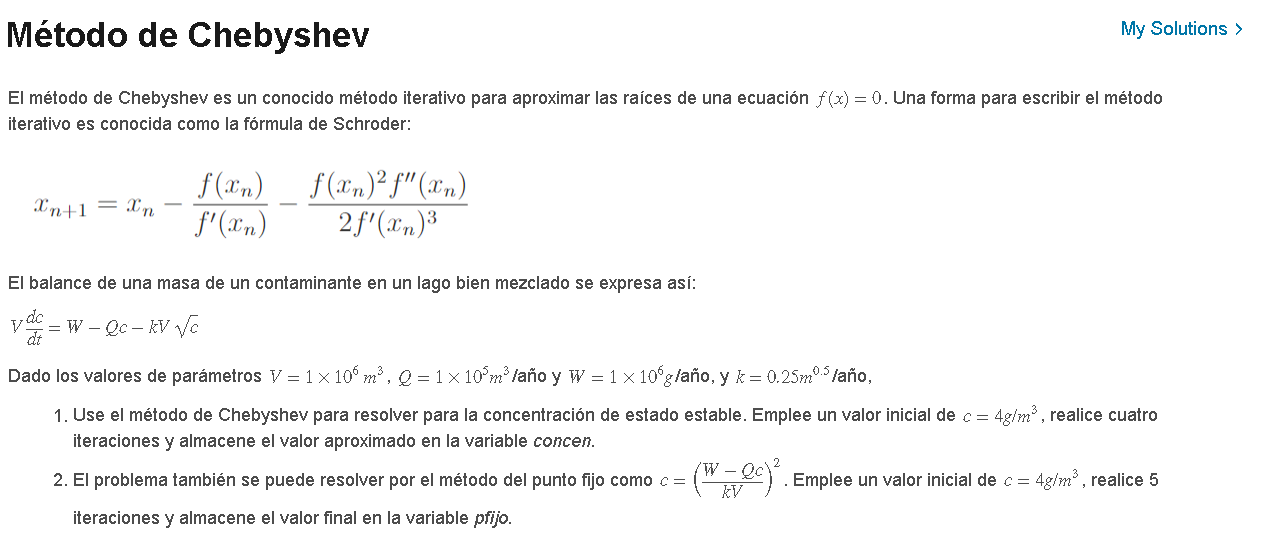

format long
syms c
V = 10^(6);
Q = 10^(5);
W = 10^(6);

k = 0.25;
c0 = 4;
n=4;

h = matlabFunction((W-Q*c-k*V*sqrt(c))/V);

historial=chebyshev(h,4,n);
concen=historial(end)

concen =    4.624080932040348



g1=@(c) ( (W-(Q*c))/(k*V))^2

g1 = function_handle with value:
    @(c)((W-(Q*c))/(k*V))^2


pfijo=puntofijo(g1,4,20)

pfijo =    4.000000000000000
   5.760000000000000
   2.876416000000000
   8.119271840808961
   0.565942145403858
  14.240231616618749
   2.876730266011721
   8.118555472504553
   0.566373361606810
  14.238929848416255


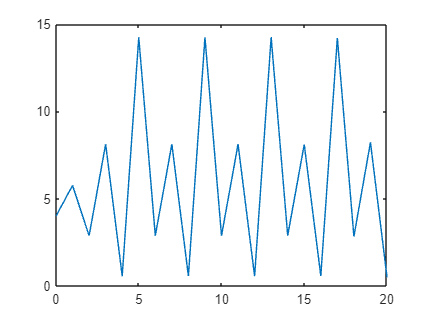


xx = [0:20];
yy = pfijo;
plot(xx,yy)


g2 = matlabFunction(W/Q-k*V*sqrt(c)/Q)

g2 = function_handle with value:
    @(c)sqrt(c).*(-5.0./2.0)+1.0e+1



pfijo2 = puntofijo(g2,4,20)

pfijo2 =    4.000000000000000
   5.000000000000000
   4.409830056250525
   4.750101157968301
   4.551318302809213
   4.666545266662744
   4.599452998385983
   4.638416163118179
   4.615754368577840
   4.628923310581806


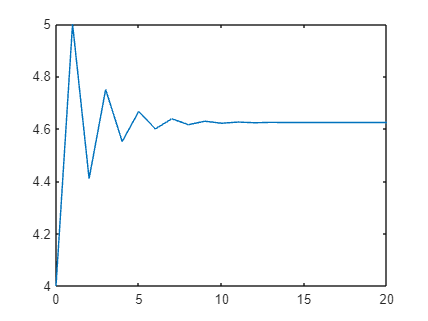


xx = [0:20];
yy = pfijo2;

plot(xx,yy)

function z=biseccion(f,a,b,Maxiter)
c=(a+b)/2;
error=(b-a)/2;
z=[a b c f(a) f(b) f(c) error];
for k=1:Maxiter
    if f(a)*f(c)<0
    b=c;
    else
    a=c;
    end
    c=(a+b)/2;
    error=(b-a)/2;
    z=[z;a b c f(a) f(b) f(c) error];
end
[row col] = size(z)
fprintf('Se necesita %d iteraciones\n',(row-1))
end




function z=biseccion2(f,a,b,Tol)
    c=(a+b)/2;
    error=(b-a)/2;
    z=[a b c f(a) f(b) f(c) error];
    N=ceil(log((b-a)/(2*Tol))/log(2));
    fprintf('Se necesita %d iteraciones\n',N)
    
    while error>Tol
        if f(a)*f(c)<0
        b=c;
        else
        a=c;
        end
        c=(a+b)/2;
        error=(b-a)/2;
        z=[z; a b c f(a) f(b) f(c) error];
    end

end


function z=newton(f,x0,Tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=x0;
error=1;
while error>Tol
    x1=x0-f(x0)/dfu(x0);
    z=[z;x1];
    error=abs(x1-x0)/abs(x1);
    x0=x1;
end
[row col] = size(z)
fprintf('Se necesita %d iteraciones\n',(row-1))
end


function z=chebyshev(f, x0, n)
syms c
Df = matlabFunction( diff(f(c)) );
DDf = matlabFunction(diff(Df(c)));
z = x0;

for i = 1:n
    xi = x0-f(x0)/Df(x0)-( (f(x0)^(2))*DDf(x0) )/( 2*(Df(x0)^(3)) );
    z = [z;xi];
    x0=xi;
end
end

function z = puntofijo(g, x0, maxIter)
    x = x0;
    iter = 0;
    z=x0;
    while iter < maxIter
        x_prev = x;
        x = g(x_prev);
        iter = iter + 1;
        z=[z;x];
    end
end



function z=puntofijo2(g,x0,tol)
z = [x0 -1];
while 1
    xi = g(x0);
    error = abs(xi-x0)/abs(xi);
    if(error<tol) 
        break
    end
    z = [z;xi error];
    x0 = xi;
end
[row col] = size(z)
fprintf('Se necesita %d iteraciones\n',(row-1))

end